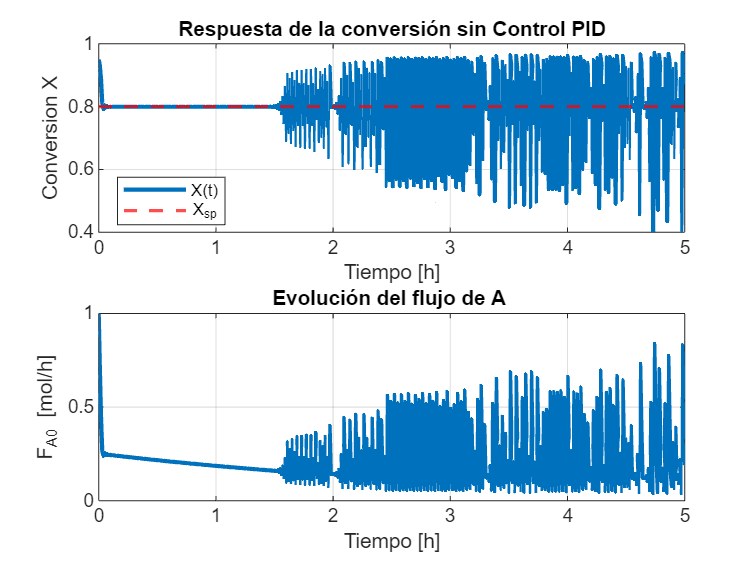

clear; clc; close all;

%% ========== [1] PARÁMETROS DEL REACTOR Y DEL MODELO ========== %%
params.k  = 0.5;     % Constante cinética 
params.V  = 2.0;     % Volumen del reactor normalizado
params.q  = 0.1;     % Caudal de salida normalizado
%

% Condición inicial normalizada
NA0 = 1;   % [mol]

%% ========== [2] TIEMPO DE SIMULACIÓN EN HORAS ========== %%
t_end = 5;         % 5 horas de simulación
dt    = 0.01;     
time  = 0:dt:t_end;

%% ========== [3] PARÁMETROS DEL PID (IMPLEMENTACIÓN MANUAL) ========== %%
% Estos son valores de partida si deseas un control "manual".
% Luego, más abajo, usaremos pidtune para obtener otro compensador.
Kp = 2.0;
Ki = 0.5;
Kd = 0.0;

% Inicializamos memoria interna del PID
error_int  = 0;  
error_prev = 0;

% Valor inicial del flujo normalizado F_A0
F_A0 = 1;

% Límites del actuador (F_A0):
F_A0_min = 0;
F_A0_max = 10;

%% ========== [4] SETPOINT DE CONVERSIÓN ========== %%
X_sp = 0.80;  % Queremos 80% de conversión

%% ========== [5] VECTORES PARA ALMACENAR DATOS DINÁMICOS ========== %%
NA_vec   = zeros(size(time));  % Moles de A en el reactor
X_vec    = zeros(size(time));  % Conversión
F_A0_vec = zeros(size(time));  % Flujo de A manipulado

% Estado inicial:
NA = NA0;

%% ========== [6] BUCLE DE SIMULACIÓN NO LINEAL CON CONTROL PID ========== %%
for i = 1:length(time)
    t_current = time(i);

    % Resolver ODE en el intervalo [t_current, t_current + dt] usando ode45
    [tout, NAsol] = ode45(@(t,NA_)(modelo_cstr(t, NA_, F_A0, params)), ...
                          [t_current, t_current+dt], NA);
    % Tomamos el valor final de ese intervalo
    NA = NAsol(end);

    % Calculamos la conversión X en este instante
    CA = NA / params.V;    % concentración [mol/m^3]
    F_A = CA * params.q;   % flujo de A a la salida [mol/h]
    % Definimos la conversión: X = (F_A0 - F_A)/ F_A0
    X   = (F_A0 - F_A)/F_A0;

    % Almacenamos
    NA_vec(i)   = NA;
    X_vec(i)    = X;
    F_A0_vec(i) = F_A0;

    % --- Control PID (forma discreta sencilla) ---
    error = X_sp - X;
    error_int = error_int + error*dt;
    error_der = (error - error_prev)/dt;
    error_prev = error;

    % Ley de control
    u = Kp*error + Ki*error_int + Kd*error_der;

    % Actualizamos el flujo F_A0
    F_A0 = F_A0 + u;

    % Saturamos si excede límites físicos
    if F_A0 < F_A0_min, F_A0 = F_A0_min; end
    if F_A0 > F_A0_max, F_A0 = F_A0_max; end
end

%% ========== [7] GRAFICAR RESULTADOS DINÁMICOS ========== %%
figure('Name','Dinamica CSTR sin Control PID (en horas)','NumberTitle','off');

subplot(2,1,1)
plot(time, X_vec,'LineWidth',2); hold on;
yline(X_sp, '--r','LineWidth',1.5);
xlabel('Tiempo [h]'); ylabel('Conversion X');
title('Respuesta de la conversión sin Control PID');
legend('X(t)','X_{sp}','Location','Best');
grid on;

subplot(2,1,2)
plot(time, F_A0_vec,'LineWidth',2);
xlabel('Tiempo [h]'); ylabel('F_{A0} [mol/h]');
title('Evolución del flujo de A ');
grid on;


%% ========== [8] LINEALIZACIÓN AL FINAL (para Polos/Ceros y TF) ========== %%
% Supongamos que el último valor de NA y F_A0 son ~punto de operación:
NA_steadystate = NA;       % moles finales
F_A0_steadystate = F_A0;   % caudal manipulado final
% Conversión final (para ver si llegamos al SP):
X_final = X_vec(end);

% Calculamos derivadas parciales:
% Estado x = NA
% Ecuación: xdot = f(x,u) = F_A0 - (NA/V)*q - k*NA
%   => A = df/dx = d/dx [ - (NA/V)*q - k*NA ] = -q/V - k
%   => B = df/du = d/dF_A0 [ F_A0 ] = 1
%
% Salida y = X = (F_A0 - (NA/V)*q) / F_A0
%   => C = dX/dx en (x0,u0)
%   => D = dX/du en (x0,u0)
% Evaluamos en (NA_steadystate, F_A0_steadystate)

A = -(params.q/params.V) - params.k;
B = 1;

% Cálculo de C y D:
x0 = NA_steadystate;
u0 = F_A0_steadystate;
C_ = - (params.q)/( u0 * params.V );             % dX/dx
D_ =   (params.q * x0)/( params.V * u0^2 );       % dX/du

% Construimos el modelo lineal en espacio de estados:
sys_lin = ss(A, B, C_, D_);

% Obtenemos la función de transferencia G(s) = X(s)/F_A0(s) en torno al pto op.
G = tf(sys_lin);

%% ========== [9] MOSTRAR POLOS Y CEROS DEL SISTEMA SIN CONTROL ========== %%
disp('>>> Polos y ceros de G(s) (sistema en lazo abierto) <<<');

>>> Polos y ceros de G(s) (sistema en lazo abierto) <<<


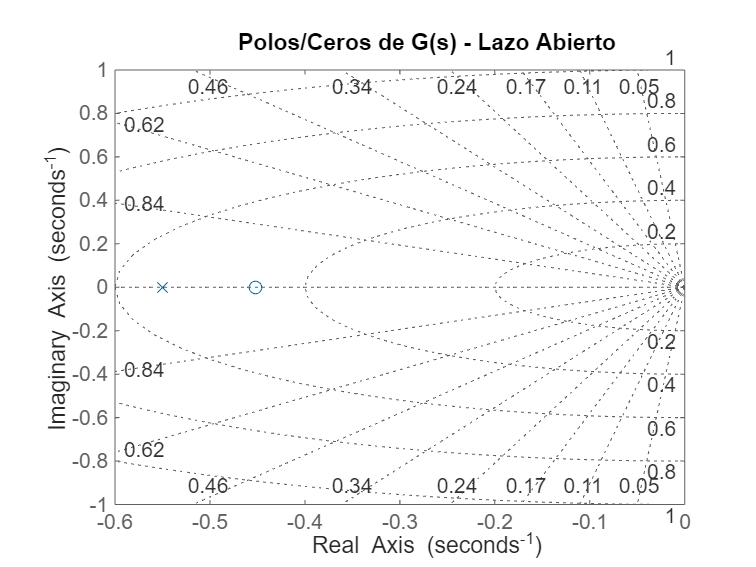

figure('Name','Polos y ceros - sistema sin controlar','NumberTitle','off');
pzmap(G); grid on; title('Polos/Ceros de G(s) - Lazo Abierto');


% Mostramos G(s) en la ventana de comandos:
disp('>>> Función de Transferencia del sistema sin control G(s) <<<');

>>> Función de Transferencia del sistema sin control G(s) <<<


G

G =
 
  10.51 s + 4.746
  ---------------
     s + 0.55
 
Continuous-time transfer function.
Model Properties



%% ========== [10] SINTONÍA PID AUTOMÁTICA (PID Tuner) ========== %%
% Usaremos pidtune para encontrar un PID que estabilice mejor G(s).
% Requerimos Control System Toolbox. Ajusta 'PID', 'PI', etc. según convenga.
try
    [Cpid, info] = pidtune(G, 'PID');
    disp('>>> Compensador PID calculado con pidtune <<<');
    Cpid
catch ME
    warning('No se pudo ejecutar pidtune. Revisa si tienes Control System Toolbox.');
    disp(ME.message);
    Cpid = tf(1);  % fallback: un "1"
end

>>> Compensador PID calculado con pidtune <<<


Cpid =
 
        1 
  Ki * ---
        s 

  with Ki = 0.099
 
Continuous-time I-only controller.
Model Properties



%% ========== [11] FUNCIÓN DE TRANSFERENCIA EN LAZO CERRADO CON ESE PID ========== %%
% T(s) = [C(s)*G(s)] / [1 + C(s)*G(s)]
T = feedback(Cpid*G, 1);

disp('>>> Polos y ceros de T(s) (sistema con PID) <<<');

>>> Polos y ceros de T(s) (sistema con PID) <<<


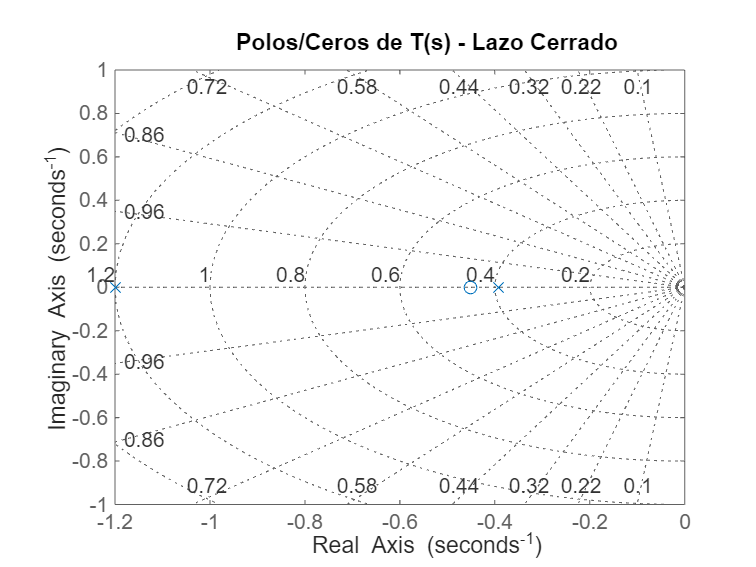

figure('Name','Polos y ceros - sistema con PID','NumberTitle','off');
pzmap(T); grid on; title('Polos/Ceros de T(s) - Lazo Cerrado');


disp('>>> Función de Transferencia en lazo cerrado T(s) = X(s)/Xsp(s) <<<');

>>> Función de Transferencia en lazo cerrado T(s) = X(s)/Xsp(s) <<<


T

T =
 
     1.04 s + 0.4698
  ---------------------
  s^2 + 1.59 s + 0.4698
 
Continuous-time transfer function.
Model Properties


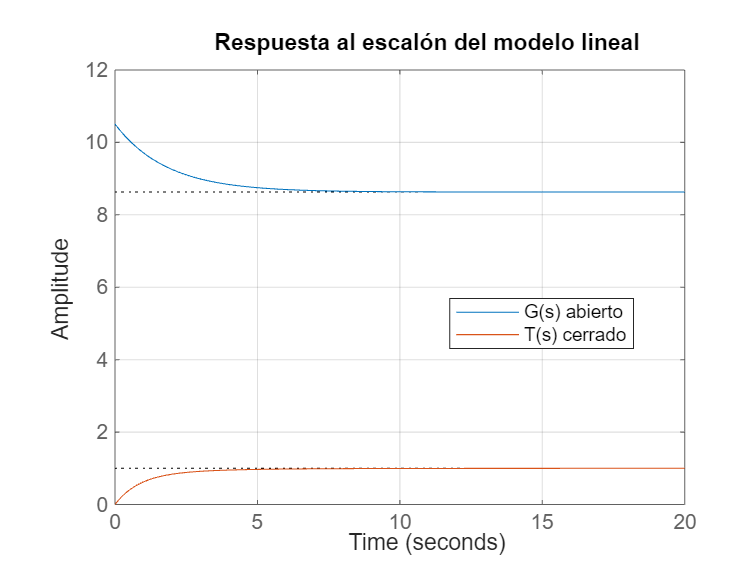


%% ========== [12] RESPUESTA AL ESCALÓN DEL SISTEMA LINEAL (COMPARACIÓN) ========== %%
% Nota: esto es la respuesta lineal (pequeñas variaciones) alrededor del pto op.
figure('Name','Respuesta al escalon - sistema lineal','NumberTitle','off');
step(G, T, 20);  % 20 h por ejemplo
legend('G(s) abierto','T(s) cerrado','Location','Best');
title('Respuesta al escalón del modelo lineal');
grid on;


%% =========================================================================
%                     FUNCION LOCAL: modelo_cstr
%% =========================================================================
function dNAdt = modelo_cstr(~, NA, F_A0, params)
    % Modelo no lineal de un CSTR:
    %   dNA/dt = F_A0 - F_A - k*NA
    %   donde F_A = (NA/V)*q
    %
    % Entradas:
    %   NA   -> moles de A dentro del reactor
    %   F_A0 -> flujo de A alimentado [mol/h] (variable manipulada)
    %   params.k, params.V, params.q
    k = params.k;
    V = params.V;
    q = params.q;

    CA    = NA / V;   % concentración de A
    F_A   = CA * q;   % flujo de A a la salida
    dNAdt = F_A0 - F_A - k*NA;
end
